clear

## Modern Controller test

load("params.mat", ...
    "sys_ss","inputs","outputs","states");

%sys_ss = ss(sys_ss.A, sys_ss.B,[1 0 0 0;0 0 1 0], 0,'statename',states,'inputname',inputs,'outputname',[outputs(1),outputs(3)])


### Preparing the statespace model

C = ctrb(sys_ss)

C = 	1.0e+04 *

         0    0.0002   -0.0020    0.0221
    0.0002   -0.0020    0.0221   -0.2434
         0    0.0011   -0.0117    0.1900
    0.0011   -0.0117    0.1900   -2.0867


rank(C)

ans = 4

As the rank of the controllability matrix is full, a controller can be implemented.

firstly the poles of the openloop is found.

pole(sys_ss)

ans =          0
  -11.5752
   -6.3737
    7.4291


%pzmap(sys)

## State feedback control

pole assignment according to Controllable cannonical form, by place in matLab.

pole_placement = [-4; -2; -1+2i; -1-2i] % LQR could be used where Q=C'C and values for cost instead of the 1's

pole_placement =   -4.0000 + 0.0000i
  -2.0000 + 0.0000i
  -1.0000 + 2.0000i
  -1.0000 - 2.0000i


F = place(sys_ss.A, sys_ss.B, pole_placement)

F =    -0.3649   -5.4226    8.0735    0.7458



A_cl = sys_ss.A-sys_ss.B*F

A_cl =          0    1.0000         0         0
    0.7298    0.8452  -14.4973   -1.5050
         0         0         0    1.0000
    4.0733    4.7174  -26.1059   -8.8452



% sys_cl = ss(A_cl,sys_ss.B,sys_ss.C,0,'statename',states,'inputname',inputs,'outputname',[outputs(1),outputs(3)])
sys_cl = ss(A_cl,sys_ss.B,sys_ss.C,0,'statename',states,'inputname',inputs,'outputname',outputs)

sys_cl =
 
  A = 
                      x    x_dot_c      theta  theta_dot
   x                  0          1          0          0
   x_dot_c       0.7298     0.8452      -14.5     -1.505
   theta              0          0          0          1
   theta_dot      4.073      4.717     -26.11     -8.845
 
  B = 
                  u
   x              0
   x_dot_c        2
   theta          0
   theta_dot  11.16
 
  C = 
                  x    x_dot_c      theta  theta_dot
   x_c            1          0          0          0
   theta          0          0          1          0
 
  D = 
          u
   x_c    0
   theta  0
 
Continuous-time state-space model.



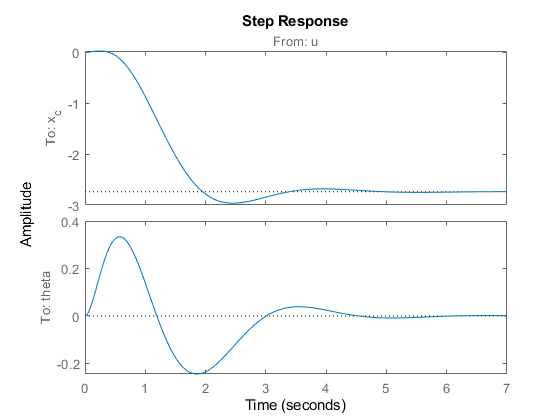

step(sys_cl)

## Observer

as the system is not full state, as only the cart position and pendulum angle is measured, an observer is needed

First the observability matrix is found from open loop

O = obsv(sys_ss.A, [1 0 0 0; 0 0 1 0])

O =     1.0000         0         0         0
         0         0    1.0000         0
         0    1.0000         0         0
         0         0         0    1.0000
         0  -10.0000    1.6498   -0.0134
         0  -55.8140   64.0173   -0.5198
         0  100.7476  -17.3551    1.7907
         0  587.1512 -125.3554   65.0351


rank(O)

ans = 4

finding eigs of A_cl

eig(A_cl)

ans =   -4.0000 + 0.0000i
  -2.0000 + 0.0000i
  -1.0000 + 2.0000i
  -1.0000 - 2.0000i



pole_obsv = [-0.23;-0.24;-0.25;-0.26] %[-4;-4.1;-4.2;-4.3]

pole_obsv =    -0.2300
   -0.2400
   -0.2500
   -0.2600


L = place(sys_ss.A', sys_ss.C', pole_obsv)'

L =    -9.4162   -0.0293
   94.9853    1.9402
  -55.2659   -0.1236
  554.4169   65.7518


implementing the loomenberger observer in A-matrix yields

Ace = [A_cl, sys_ss.B*F;zeros(size(sys_ss.A)), sys_ss.A-L*sys_ss.C]

Ace =          0    1.0000         0         0         0         0         0         0
    0.7298    0.8452  -14.4973   -1.5050   -0.7298  -10.8452   16.1471    1.4916
         0         0         0    1.0000         0         0         0         0
    4.0733    4.7174  -26.1059   -8.8452   -4.0733  -60.5313   90.1232    8.3254
         0         0         0         0    9.4162    1.0000    0.0293         0
         0         0         0         0  -94.9853  -10.0000   -0.2904   -0.0134
         0         0         0         0   55.2659         0    0.1236    1.0000
         0         0         0         0 -554.4169  -55.8140   -1.7346   -0.5198


Bce = [sys_ss.B;zeros(size(sys_ss.B))]

Bce =          0
    2.0000
         0
   11.1628
         0
         0
         0
         0


Cce = [sys_ss.C zeros(size(sys_ss.C))]

Cce =      1     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0


Dce = [0;0]

Dce =      0
     0


sys_cl = ss(Ace, Bce, Cce, Dce)

sys_cl =
 
  A = 
            x1       x2       x3       x4       x5       x6       x7       x8
   x1        0        1        0        0        0        0        0        0
   x2   0.7298   0.8452    -14.5   -1.505  -0.7298   -10.85    16.15    1.492
   x3        0        0        0        1        0        0        0        0
   x4    4.073    4.717   -26.11   -8.845   -4.073   -60.53    90.12    8.325
   x5        0        0        0        0    9.416        1  0.02926        0
   x6        0        0        0        0   -94.99      -10  -0.2904  -0.0134
   x7        0        0        0        0    55.27        0   0.1236        1
   x8        0        0        0        0   -554.4   -55.81   -1.735  -0.5198
 
  B = 
          u1
   x1      0
   x2      2
   x3      0
   x4  11.16
   x5      0
   x6      0
   x7      0
   x8      0
 
  C = 
       x1  x2  x3  x4  x5  x6  x7  x8
   y1   1   0   0   0   0   0   0   0
   y2   0   0   1   0   0   0   0   0
 
  D = 
       u1
   y1   0
  

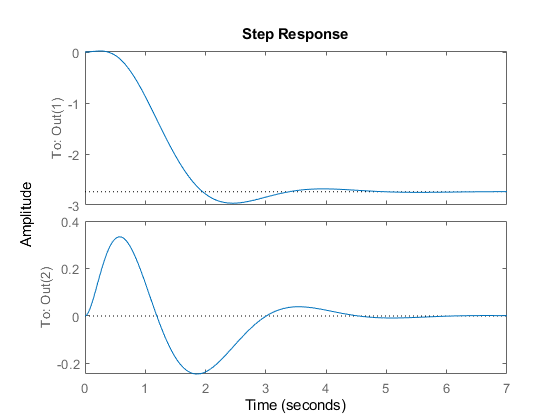


step(sys_cl)

## Reference signal

Next step, add reference signal and calculate M and N matrix